f = @(x) -0.1 * x.^4 - 0.15 * x.^3 - 0.5 * x.^2 - 0.25 * x + 1.2;
x = 0.5;
df = matlabFunction(diff(sym(f)));
dfx = df(x)

dfx = -0.9125

Primera derivada: Aproximación hacia adelante O(h)
	 h 	     aproximación 	 	 error
  1.0000000000 	 -2.23750000000000 	  1.3250000000000
  0.1000000000 	 -1.00360000000000 	  0.0911000000000
  0.0100000000 	 -0.92128509999999 	  0.0087851000000
  0.0010000000 	 -0.91337535009994 	  0.0008753500999
  0.0001000000 	 -0.91258750349987 	  0.0000875034999
  0.0000100000 	 -0.91250875002835 	  0.0000087500284
  0.0000010000 	 -0.91250087497219 	  0.0000008749722
  0.0000001000 	 -0.91250008660282 	  0.0000000866028
  0.0000000100 	 -0.91250000888721 	  0.0000000088872
  0.0000000010 	 -0.91249996447829 	  0.0000000355217
  0.0000000001 	 -0.91250007550059 	  0.0000000755006


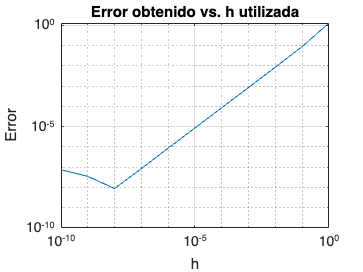

dfForward1(f, x);

Funciones auxiliares que nos ayudarán a mostrar los resultados obtenidos y desplegar la gráfica correspondiente en escala log-log.

function muestraResultados(hs, aproxs, err)
% Imprime una tabla de las h generadas, su aproximación, y el error correspondiente.
% Parámetros: h = las h utilizadas en las aproximaciones
% aproxs = los resultados de las aproximaciones
%    err = los errores obtenidos
    format long
    res = [hs' aproxs' err']';
    fprintf('\t h \t     aproximación \t \t error\n');
    fprintf('%14.10f \t %16.14f \t %16.13f\n', res);
    format short
end


function grafError(hs, err)
% Despliega la gráfica correspondiente a las h generadas y sus errores calculados, utilizando la función loglog de MATLAB.
% Parámetros: h = las h utilizadas en las aproximaciones
%    err = los errores obtenidos
    loglog(hs, err)
    grid on
    title('Error obtenido vs. h utilizada')
    xlabel('h')
    ylabel('Error')
end

PRIMERA DERIVADA

#### Aproximación hacia adelante

**Primer orden **$O\left(h\right)$

La fórmula para la aproximación hacia adelante de la primera derivada $O\left(h\right)$ es: $f^{\left(1\right)} \left(x\right)=\frac{f\left(x+h\right)-f\left(x\right)}{h}$

function [hs, aproxs, err] = ForwardOrder1(f, x, h, n)
% Realiza n veces la aproximación hacia adelante O(h) de la primera derivada.
% Parámetros: f = función a derivar
%    x = punto a aproximar
%    h = el valor inicial para h
%    n = el número de veces que se realizará la aproximación (dividiendo el
%    valor de h entre 10 en cada ciclo)
% Regresa: hs = las h utilizadas en las aproximaciones
%    aproxs = los resultados de las aproximaciones
%    err = los errores obtenidos

    if nargin(f) == 0
        error('La función es una constante o no cuenta con argumentos de entrada.')
    end
    
    fx = f(x);
    df = matlabFunction(diff(sym(f)));

    if nargin(df) == 0
        df = @(x) df();
        warning('La primera derivada de la función es una constante.')
    end
    
    dfx = df(x);
    hs = NaN(1, n);
    aproxs = NaN(1, n);
    err = NaN(1, n);
    i = 1;
    
    while i <= n
        aprx = (f(x + h) - fx) / h;
        aproxs(i) = aprx;
        err(i) = abs(dfx - aprx);
        hs(i) = h;
        h = h / 10;
        i = i + 1;
    end
end



function dfForward1(f, x)
% Realiza la aproximación hacia adelante O(h) de la primera derivada, con 
% h = [10^0, 10^-10]. Además, imprime una tabla de las h generadas, su aproximación, y el error correspondiente. También genera la gráfica del error vs. la h utilizada.
% Parámetros: f = función a derivar
%    x = punto a aproximar

    [hs, aprxs, err] = ForwardOrder1(f, x, 1, 11);
    fprintf('Primera derivada: Aproximación hacia adelante O(h)\n');
    muestraResultados(hs, aprxs, err)
    grafError(hs, err)
end

**Segundo orden **$O\left(h^2 \right)$

La fórmula para la aproximación hacia adelante de la primera derivada $O\left(h^2 \right)$ es: $f^{\left(1\right)} \left(x\right)=\frac{-\frac{1}{2}f\left(x+2h\right)+2f\left(x+h\right)-\frac{3}{2}f\left(x\right)}{h}=\frac{-f\left(x+2h\right)+4f\left(x+h\right)-3f\left(x\right)}{2h}$

function [hs, aprxs, err] = ForwardOrder2(f, x, h, n)
% Realiza n veces la aproximación hacia adelante O(h^2) de la primera derivada.
% Parámetros: f = función a derivar
%    x = punto a aproximar
%    h = el valor inicial para h
%    n = el número de veces que se realizará la aproximación (dividiendo el
%    valor de h entre 10 en cada ciclo)
% Regresa: hs = las h utilizadas en las aproximaciones
%    aprxs = los resultados de las aproximaciones
%    err = los errores obtenidos

    if nargin(f) == 0
        error('La función es una constante o no cuenta con argumentos de entrada.')
    end
    
    fx = f(x);
    df = matlabFunction(diff(sym(f)));

    if nargin(df) == 0
        df = @(x) df();
        warning('La primera derivada de la función es una constante.')
    end
    
    dfx = df(x);
    hs = NaN(1, n);
    aprxs = NaN(1, n);
    err = NaN(1, n);
    i = 1;
    
    while i <= n
        aprx = (-f(x + 2 * h) + 4 * f(x + h) - 3 * fx) / (2 * h);
        aprxs(i) = aprx;
        err(i) = abs(dfx - aprx);
        hs(i) = h;
        h = h / 10;
        i = i + 1;
    end
end


function dfForward2(f, x)
% Realiza la aproximación hacia adelante O(h^2) de la primera derivada, con 
% h = [10^0, 10^-10]. Además, imprime una tabla de las h generadas, su
% aproximación, y el error correspondiente. También genera la gráfica del
% error vs. la h utilizada.
% Parámetros: f = función a derivar
%    x = punto a aproximar

    [hs, aprxs, err] = ForwardOrder2(f, x, 1, 11);
    fprintf('Primera derivada: Aproximación hacia adelante O(h^2)\n');
    muestraResultados(hs, aprxs, err)
    grafError(hs, err)
end

#### Aproximación centrada $O\left(h^2 \right)$

La fórmula para la aproximación centrada de la primera derivada $O\left(h^2 \right)$ es: $f^{\left(1\right)} \left(x\right)=\frac{\frac{1}{2}f\left(x+h\right)-\frac{1}{2}f\left(x-h\right)}{h}=\frac{f\left(x+h\right)-f\left(x-h\right)}{2h}$

function [hs, aprxs, err] = DerCentral(f, x, h, n)
% Realiza n veces la aproximación centrada O(h^2) de la primera derivada.
% Parámetros: f = función a derivar
%    x = punto a aproximar
%    h = el valor inicial para h
%    n = el número de veces que se realizará la aproximación (dividiendo el
%    valor de h entre 10 en cada ciclo)
% Regresa: hs = las h utilizadas en las aproximaciones
%    aprxs = los resultados de las aproximaciones
%    err = los errores obtenidos

    if nargin(f) == 0
        error('La función es una constante o no cuenta con argumentos de entrada.')
    end
    
    df = matlabFunction(diff(sym(f)));

    if nargin(df) == 0
        df = @(x) df();
        warning('La primera derivada de la función es una constante.')
    end
    
    dfx = df(x);
    hs = NaN(1, n);
    aprxs = NaN(1, n);
    err = NaN(1, n);
    i = 1;
    
    while i <= n
        aprx = (f(x + h) - f(x - h)) / (2 * h);
        aprxs(i) = aprx;
        err(i) = abs(dfx - aprx);
        hs(i) = h;
        h = h / 10;
        i = i + 1;
    end
end


function dfCentral(f, x)
% Realiza la aproximación centrada O(h^2) de la primera derivada, con 
% h = [10^0, 10^-10]. Además, imprime una tabla de las h generadas, su
% aproximación, y el error correspondiente. También genera la gráfica del
% error vs. la h utilizada.
% Parámetros:
%    f = función a derivar
%    x = punto a aproximar

    [hs, aprxs, err] = DerCentral(f, x, 1, 11);
    fprintf('Primera derivada: Aproximación centrada O(h^2)\n');
    muestraResultados(hs, aprxs, err)
    grafError(hs, err)
end


#### Aproximación hacia atrás

**Primer orden **$O\left(h\right)$

La fórmula para la aproximación hacia atrás de la primera derivada $O\left(h\right)$ es: $f^{\left(1\right)} \left(x\right)=\frac{f\left(x\right)-f\left(x-h\right)}{h}$

function [hs, aprxs, err] = BackwardOrder1(f, x, h, n)
% Realiza n veces la aproximación hacia atrás O(h) de la primera derivada.
% Parámetros: f = función a derivar
%    x = punto a aproximar
%    h = el valor inicial para h
%    n = el número de veces que se realizará la aproximación (dividiendo el
%    valor de h entre 10 en cada ciclo)
% Regresa: hs = las h utilizadas en las aproximaciones
%    aprxs = los resultados de las aproximaciones
%    err = los errores obtenidos

    if nargin(f) == 0
        error('La función es una constante o no cuenta con argumentos de entrada.')
    end
    
    fx = f(x);    
    df = matlabFunction(diff(sym(f)));

    if nargin(df) == 0
        df = @(x) df();
        warning('La primera derivada de la función es una constante.')
    end
    
    dfx = df(x);
    hs = NaN(1, n);
    aprxs = NaN(1, n);
    err = NaN(1, n);
    i = 1;
    
    while i <= n
        aprx = (fx - f(x - h)) / h;
        aprxs(i) = aprx;
        err(i) = abs(dfx - aprx);
        hs(i) = h;
        h = h / 10;
        i = i + 1;
    end
end


function dfBackward1(f, x)
% Realiza la aproximación hacia atrás O(h) de la primera derivada, con 
% h = [10^0, 10^-10]. Además, imprime una tabla de las h generadas, su
% aproximación, y el error correspondiente. También genera la gráfica del
% error vs. la h utilizada.
% Parámetros: f = función a derivar
%    x = punto a aproximar

    [hs, aprxs, err] = BackwardOrder1(f, x, 1, 11);
    fprintf('Primera derivada: Aproximación hacia atrás O(h)\n');
    muestraResultados(hs, aprxs, err)
    grafError(hs, err)
end

**Segundo orden **$O\left(h^2 \right)$

La fórmula para la aproximación hacia atrás de la primera derivada $O\left(h^2 \right)$ es: $f^{\left(1\right)} \left(x\right)=\frac{\frac{3}{2}f\left(x\right)-2f\left(x-h\right)+\frac{1}{2}f\left(x-2h\right)}{h}=\frac{3f\left(x\right)-4f\left(x-h\right)+f\left(x-2h\right)}{2h}$

function [hs, aprxs, err] = BackwardOrder2(f, x, h, n)
% Realiza n veces la aproximación hacia atrás O(h^2) de la primera
% derivada.
% Parámetros: f = función a derivar
%    x = punto a aproximar
%    h = el valor inicial para h
%    n = el número de veces que se realizará la aproximación (dividiendo el
%    valor de h entre 10 en cada ciclo)
% Regresa: hs = las h utilizadas en las aproximaciones
%    aprxs = los resultados de las aproximaciones
%    err = los errores obtenidos

    if nargin(f) == 0
        error('La función es una constante o no cuenta con argumentos de entrada.')
    end
    
    fx = f(x);    
    df = matlabFunction(diff(sym(f)));

    if nargin(df) == 0
        df = @(x) df();
        warning('La primera derivada de la función es una constante.')
    end
    
    dfx = df(x);
    hs = NaN(1, n);
    aprxs = NaN(1, n);
    err = NaN(1, n);
    i = 1;
    
    while i <= n
        aprx = (3 * fx - 4 * f(x - h) + f(x - 2 * h)) / (2 * h);
        aprxs(i) = aprx;
        err(i) = abs(dfx - aprx);
        hs(i) = h;
        h = h / 10;
        i = i + 1;
    end
end


function dfBackward2(f, x)
% Realiza la aproximación hacia atrás O(h^2) de la primera derivada, con 
% h = [10^0, 10^-10]. Además, imprime una tabla de las h generadas, su
% aproximación, y el error correspondiente. También genera la gráfica del
% error vs. la h utilizada.
% Parámetros: f = función a derivar
%    x = punto a aproximar

    [hs, aprxs, err] = BackwardOrder2(f, x, 1, 11);
    fprintf('Primera derivada: Aproximación hacia atrás O(h^2)\n');
    muestraResultados(hs, aprxs, err)
    grafError(hs, err)
end

SEGUNDA DERIVADA

Se observó que las fórmulas para la segunda derivada en primer y segundo orden son IGUALES en los casos: Adelante y Atras, por lo que solo se codificara una vez.

#### Aproximación hacia adelante

**Primer orden **$O\left(h\right)$

La fórmula para la aproximación hacia adelante (y análogamente hacia atrás) de la segunda derivada $O\left(h\right)$ es: $f^{\left(2\right)} \left(x\right)=\frac{f\left(x+2h\right)-2f\left(x+h\right)+f\left(x\right)}{h^2 }$

function [hs, aprxs, err] = segForwardOrder1(f, x, h, n)
% Realiza n veces la aproximación hacia adelante O(h) de la segunda
% derivada.
% Parámetros: f = función a derivar
%    x = punto a aproximar
%    h = el valor inicial para h
%    n = el número de veces que se realizará la aproximación (dividiendo el
%    valor de h entre 10 en cada ciclo)
% Regresa: hs = las h utilizadas en las aproximaciones
%    aprxs = los resultados de las aproximaciones
%    err = los errores obtenidos

    if nargin(f) == 0
        error('La función es una constante o no cuenta con argumentos de entrada.')
    end
    
    fx = f(x);    
    ddf = matlabFunction(diff(diff(sym(f))));
    
    if nargin(ddf) == 0
        ddf = @(x) ddf();
        warning('La segunda derivada de la función es una constante.')
    end
    
    ddfx = ddf(x);
    hs = NaN(1, n);
    aprxs = NaN(1, n);
    err = NaN(1, n);
    i = 1;
    
    while i <= n
        aprx = (f(x + 2 * h) - 2 * f(x + h) + fx) / h ^ 2;
        aprxs(i) = aprx;
        err(i) = abs(ddfx - aprx);
        hs(i) = h;
        h = h / 10;
        i = i + 1;
    end
end


function ddfForward1(f, x)
% Realiza la aproximación hacia adelante O(h) de la segunda derivada, con 
% h = [10^0, 10^-10]. Además, imprime una tabla de las h generadas, su
% aproximación, y el error correspondiente. También genera la gráfica del
% error vs. la h utilizada.
% Parámetros:
%    f = función a derivar
%    x = punto a aproximar

    [hs, aprxs, err] = segForwardOrder1(f, x, 1, 11);
    fprintf('Segunda derivada: Aproximación hacia adelante O(h)\n');
    muestraResultados(hs, aprxs, err)
    grafError(hs, err)
end

**Segundo orden **$O\left(h^2 \right)$

La fórmula para la aproximación hacia adelante (y análogamente hacia atrás) de la segunda derivada $O\left(h^2 \right)$ es: $f^{\left(2\right)} \left(x\right)=\frac{-f\left(x+3h\right)+4f\left(x+2h\right)-5f\left(x+h\right)+2f\left(x\right)}{h^2 }$

function [hs, aprxs, err] = segForwardOrder2(f, x, h, n)
% Realiza n veces la aproximación hacia adelante O(h^2) de la segunda
% derivada.
% Parámetros: f = función a derivar
%    x = punto a aproximar
%    h = el valor inicial para h
%    n = el número de veces que se realizará la aproximación (dividiendo el
%    valor de h entre 10 en cada ciclo)
% Regresa: hs = las h utilizadas en las aproximaciones
%    aprxs = los resultados de las aproximaciones
%    err = los errores obtenidos

    if nargin(f) == 0
        error('La función es una constante o no cuenta con argumentos de entrada.')
    end
    
    fx = f(x);    
    ddf = matlabFunction(diff(diff(sym(f))));
    
    if nargin(ddf) == 0
        ddf = @(x) ddf();
        warning('La segunda derivada de la función es una constante.')
    end
    
    ddfx = ddf(x);
    hs = NaN(1, n);
    aprxs = NaN(1, n);
    err = NaN(1, n);
    i = 1;
    
    while i <= n
        aprx = (-f(x + 3 * h) + 4 * f(x + 2 * h) - 5 * f(x + h) + 2 * fx) / h ^ 2;
        aprxs(i) = aprx;
        err(i) = abs(ddfx - aprx);
        hs(i) = h;
        h = h / 10;
        i = i + 1;
    end
end


function ddfForward2(f, x)
% Realiza la aproximación hacia adelante O(h^2) de la segunda derivada, con 
% h = [10^0, 10^-10]. Además, imprime una tabla de las h generadas, su
% aproximación, y el error correspondiente. También genera la gráfica del
% error vs. la h utilizada.
% Parámetros:
%    f = función a derivar
%    x = punto a aproximar

    [hs, aprxs, err] = segForwardOrder2(f, x, 1, 11);
    fprintf('Segunda derivada: Aproximación hacia adelante O(h^2)\n');
    muestraResultados(hs, aprxs, err)
    grafError(hs, err)
end

#### Aproximación centrada $O\left(h^2 \right)$

La fórmula para la aproximación centrada de la segunda derivada $O\left(h^2 \right)$ es: $f^{\left(2\right)} \left(x\right)=\frac{f\left(x+h\right)-2f\left(x\right)+f\left(x-h\right)}{h^2 }$

function [hs, aprxs, err] = segDerCentral(f, x, h, n)
% Realiza n veces la aproximación centrada O(h^2) de la segunda derivada.
% Parámetros: f = función a derivar
%    x = punto a aproximar
%    h = el valor inicial para h
%    n = el número de veces que se realizará la aproximación (dividiendo el
%    valor de h entre 10 en cada ciclo)
% Regresa: hs = las h utilizadas en las aproximaciones
%    aprxs = los resultados de las aproximaciones
%    err = los errores obtenidos

    if nargin(f) == 0
        error('La función es una constante o no cuenta con argumentos de entrada.')
    end
    
    fx = f(x);    
    ddf = matlabFunction(diff(diff(sym(f))));
    
    if nargin(ddf) == 0
        ddf = @(x) ddf();
        warning('La segunda derivada de la función es una constante.')
    end
    
    ddfx = ddf(x);
    hs = NaN(1, n);
    aprxs = NaN(1, n);
    err = NaN(1, n);
    i = 1;
    
    while i <= n
        aprx = (f(x + h) - 2 * fx + f(x - h)) / h ^ 2;
        aprxs(i) = aprx;
        err(i) = abs(ddfx - aprx);
        hs(i) = h;
        h = h / 10;
        i = i + 1;
    end
end


function ddfCentral(f, x)
% Realiza la aproximación centrada O(h^2) de la segunda derivada, con 
% h = [10^0, 10^-10]. Además, imprime una tabla de las h generadas, su
% aproximación, y el error correspondiente. También genera la gráfica del
% error vs. la h utilizada.
% Parámetros: f = función a derivar
%    x = punto a aproximar

    [hs, aprxs, err] = segDerCentral(f, x, 1, 11);
    fprintf('Segunda derivada: Aproximación centrada O(h^2)\n');
    muestraResultados(hs, aprxs, err)
    grafError(hs, err)
end
